%% Spike sorting figure : show qualitym correlqtion of spike shape, IN vs PN

%% This codes looks at what neurons are doing
clear all, close all

MiceNumber=[490,507,508,509,510,512,514]; % add 509 back in later
SessNames={'EPM','Habituation' 'SleepPreUMaze' 'TestPre' 'UMazeCond' 'SleepPostUMaze' 'TestPost' 'Extinction',...
    'SoundHab' 'SleepPreSound' 'SoundCond' 'SleepPostSound' 'SoundTest'};
GoodLongSess=[3,6,10,12]; % the sleep sessions --> long enough to guarantee enough spikes
TestPre=[4,5,6,7];
Umaze=[8,9,10,11,12];
TestPost=[14,15,16,17];


for mm=1:length(MiceNumber)
    FileNames=GetAllMouseTaskSessions(MiceNumber(mm));
    for ss=1:length(FileNames)
        cd(FileNames{ss})
        load('MeanWaveform.mat')
        NumSpk{mm}(ss)=length(W);
    
    
    for k=1:length(W)
        try
            AllWF{mm}{k}(ss,:)=runmean(reshape(W{k}',1,size(W{k},1)*size(W{k},2)),1);
        catch
            AllWF{mm}{k}(ss,:)=NaN(1,length(AllWF{1}{1}(1,:)));
        end
    end
    end
    
    for k=1:length(AllWF{mm})
        % Replace these many short sessions with the average over all the
        % sessions
        AllWF{mm}{k}(TestPre(1),:)=mean(AllWF{mm}{k}(TestPre,:));
        AllWF{mm}{k}(TestPost(1),:)=mean(AllWF{mm}{k}(TestPost,:));
        AllWF{mm}{k}(Umaze(1),:)=mean(AllWF{mm}{k}(Umaze,:));
        AllWF{mm}{k}(TestPost(2:end),:)=[];
        AllWF{mm}{k}(Umaze(2:end),:)=[];
        AllWF{mm}{k}(TestPre(2:end),:)=[];
        
        % All sessions
        rho=corr(AllWF{mm}{k}');
        MinCorr{mm}(k)=min(rho(:));
        MeanCorr{mm}(k)=mean(rho(:));
        MedianCorr{mm}(k)=median(rho(:));
        EucDist=pdist(AllWF{mm}{k})./size(AllWF{mm}{k},2);
        MaxEucDist{mm}(k)=max(EucDist(:));
        MeanEucDist{mm}(k)=mean(EucDist(:));
        MedianEucDist{mm}(k)=median(EucDist(:));
        
        % Just sleep sessions so we're sure to have enough data
        rho=rho(GoodLongSess,GoodLongSess);
        MinCorrSlOnly{mm}(k)=min(rho(:));
        MeanCorrSlOnly{mm}(k)=mean(rho(:));
        MedianCorrSlOnly{mm}(k)=median(rho(:));
        EucDist=pdist(AllWF{mm}{k}(GoodLongSess,:))./size(AllWF{mm}{k},2);
        MaxEucDistSlOnly{mm}(k)=max(EucDist(:));
        MeanEucDistSlOnly{mm}(k)=mean(EucDist(:));
        MedianEucDistSlOnly{mm}(k)=median(EucDist(:));
    end
end

Euclidian distance -all session

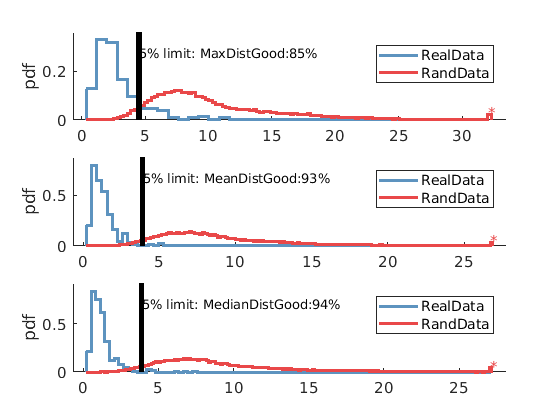

EucDisttemp=[];
for ss=1:13
    AllWFSess=[];
    for mm=1:length(MiceNumber)
        for k=1:length(AllWF{mm})
            if size(AllWF{mm}{k},2)==128
                AllWFSess=[AllWFSess;AllWF{mm}{k}(ss,:)];
            end
        end
    end
    EucDisttemp(ss,:)=pdist(AllWFSess)./128;
end


figure
subplot(311)
nhist({[MaxEucDist{:}],max(EucDisttemp)},'noerror'); hold on
Lim= prctile(max(EucDisttemp),5);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(Lim+0.01,max(ylim)*0.75,['5% limit: MaxDistGood:',num2str(round(100*sum([MaxEucDist{:}]<Lim)/length([MaxEucDist{:}]))),'%'])
legend({'RealData','RandData'})
subplot(312)
nhist({[MeanEucDist{:}],nanmean(EucDisttemp)},'noerror'); hold on
Lim= prctile(nanmean(EucDisttemp),5);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(Lim+0.01,max(ylim)*0.75,['5% limit: MeanDistGood:',num2str(round(100*sum([MeanEucDist{:}]<Lim)/length([MeanEucDist{:}]))),'%'])
legend({'RealData','RandData'})
subplot(313)
nhist({[MedianEucDist{:}],nanmedian(EucDisttemp)},'noerror'); hold on
Lim= prctile(nanmedian(EucDisttemp),5);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(Lim+0.01,max(ylim)*0.75,['5% limit: MedianDistGood:',num2str(round(100*sum([MedianEucDist{:}]<Lim)/length([MedianEucDist{:}]))),'%'])
legend({'RealData','RandData'})

Euclidian distance - just sleep sessions

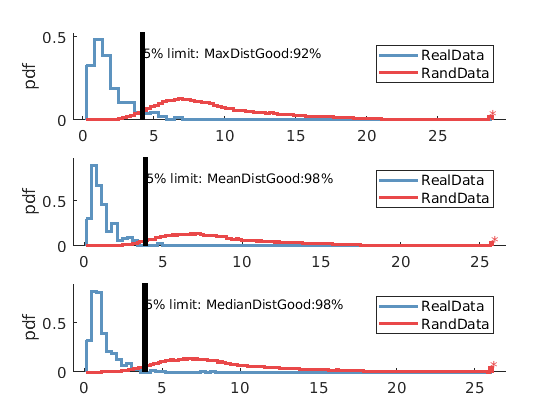



EucDisttemp=[];
for ss=1:length(GoodLongSess)
    AllWFSess=[];
    for mm=1:length(MiceNumber)
        for k=1:length(AllWF{mm})
            if size(AllWF{mm}{k},2)==128
                AllWFSess=[AllWFSess;AllWF{mm}{k}(GoodLongSess(ss),:)];
            end
        end
    end
    EucDisttemp(ss,:)=pdist(AllWFSess)./128;
end


figure
subplot(311)
nhist({[MaxEucDistSlOnly{:}],max(EucDisttemp)},'noerror'); hold on
Lim= prctile(max(EucDisttemp),5);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(Lim+0.01,max(ylim)*0.75,['5% limit: MaxDistGood:',num2str(round(100*sum([MaxEucDistSlOnly{:}]<Lim)/length([MaxEucDistSlOnly{:}]))),'%'])
legend({'RealData','RandData'})
subplot(312)
nhist({[MeanEucDistSlOnly{:}],nanmean(EucDisttemp)},'noerror'); hold on
Lim= prctile(nanmean(EucDisttemp),5);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(Lim+0.01,max(ylim)*0.75,['5% limit: MeanDistGood:',num2str(round(100*sum([MeanEucDistSlOnly{:}]<Lim)/length([MeanEucDistSlOnly{:}]))),'%'])
legend({'RealData','RandData'})
subplot(313)
nhist({[MedianEucDistSlOnly{:}],nanmedian(EucDisttemp)},'noerror'); hold on
Lim= prctile(nanmedian(EucDisttemp),5);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(Lim+0.01,max(ylim)*0.75,['5% limit: MedianDistGood:',num2str(round(100*sum([MedianEucDistSlOnly{:}]<Lim)/length([MedianEucDistSlOnly{:}]))),'%'])
legend({'RealData','RandData'})

Correlation Measure - all sessions

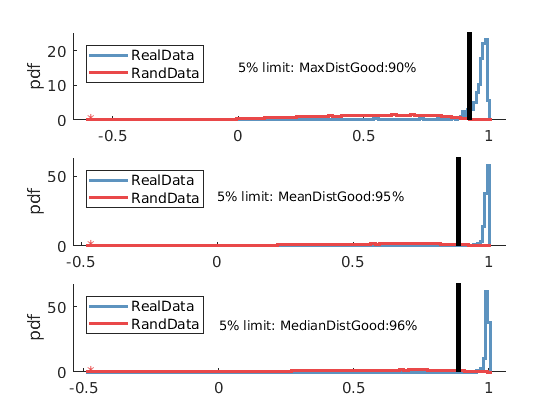


EucDisttemp=[];
for ss=1:13
    AllWFSess=[];
    for mm=1:length(MiceNumber)
        for k=1:length(AllWF{mm})
            if size(AllWF{mm}{k},2)==128
                AllWFSess=[AllWFSess;AllWF{mm}{k}(ss,:)];
            end
        end
    end
    temp=triu(corr(AllWFSess'),1);temp(temp==0)=NaN; % get rid of zeos that form bottom half of matrix
    EucDisttemp(ss,:)=temp(:);
end


figure
subplot(311)
nhist({[MinCorr{:}],min(EucDisttemp)},'noerror'); hold on
Lim= prctile(max(EucDisttemp),95);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(0,15,['5% limit: MaxDistGood:',num2str(round(100*sum([MinCorr{:}]>Lim)/length([MinCorr{:}]))),'%'])
legend({'RealData','RandData'},'Location','northwest')
subplot(312)
nhist({[MeanCorr{:}],nanmean(EucDisttemp)},'noerror'); hold on
Lim= prctile(nanmean(EucDisttemp),95);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(0,35,['5% limit: MeanDistGood:',num2str(round(100*sum([MeanCorr{:}]>Lim)/length([MeanCorr{:}]))),'%'])
legend({'RealData','RandData'},'Location','northwest')
subplot(313)
nhist({[MedianCorr{:}],nanmedian(EucDisttemp)},'noerror'); hold on
Lim= prctile(nanmedian(EucDisttemp),95);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(0,35,['5% limit: MedianDistGood:',num2str(round(100*sum([MedianCorr{:}]>Lim)/length([MedianCorr{:}]))),'%'])
legend({'RealData','RandData'},'Location','northwest')

Correlation Measure - sleep sessions

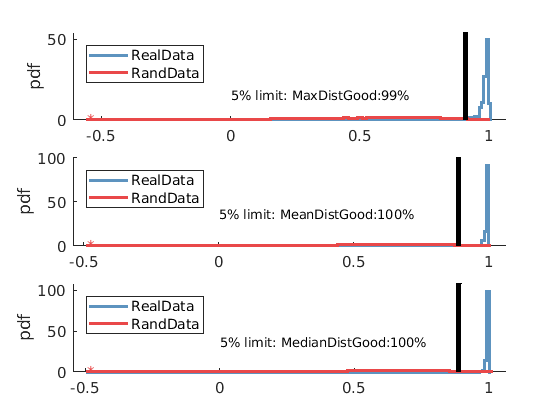

EucDisttemp=[];
for ss=1:length(GoodLongSess)
    AllWFSess=[];
    for mm=1:length(MiceNumber)
        for k=1:length(AllWF{mm})
            if size(AllWF{mm}{k},2)==128
                AllWFSess=[AllWFSess;AllWF{mm}{k}(GoodLongSess(ss),:)];
            end
        end
    end
    temp=triu(corr(AllWFSess'),1);temp(temp==0)=NaN; % get rid of zeos that form bottom half of matrix
    EucDisttemp(ss,:)=temp(:);
end


figure
subplot(311)
nhist({[MinCorrSlOnly{:}],min(EucDisttemp)},'noerror'); hold on
Lim= prctile(max(EucDisttemp),95);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(0,15,['5% limit: MaxDistGood:',num2str(round(100*sum([MinCorrSlOnly{:}]>Lim)/length([MinCorrSlOnly{:}]))),'%'])
legend({'RealData','RandData'},'Location','northwest')
subplot(312)
nhist({[MeanCorrSlOnly{:}],nanmean(EucDisttemp)},'noerror'); hold on
Lim= prctile(nanmean(EucDisttemp),95);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(0,35,['5% limit: MeanDistGood:',num2str(round(100*sum([MeanCorrSlOnly{:}]>Lim)/length([MeanCorrSlOnly{:}]))),'%'])
legend({'RealData','RandData'},'Location','northwest')
subplot(313)
nhist({[MedianCorrSlOnly{:}],nanmedian(EucDisttemp)},'noerror'); hold on
Lim= prctile(nanmedian(EucDisttemp),95);
line([Lim Lim],ylim,'linewidth',4,'color','k')
text(0,35,['5% limit: MedianDistGood:',num2str(round(100*sum([MedianCorrSlOnly{:}]>Lim)/length([MedianCorrSlOnly{:}]))),'%'])
legend({'RealData','RandData'},'Location','northwest')